# Dynamical Diffusion map

Please refer to [Lin, Malik and Wu (2019)](https://arxiv.org/abs/1907.00502).

## RR interval

Please refer to [Li, Frasch and Wu (2017)](https://arxiv.org/abs/1702.02025)

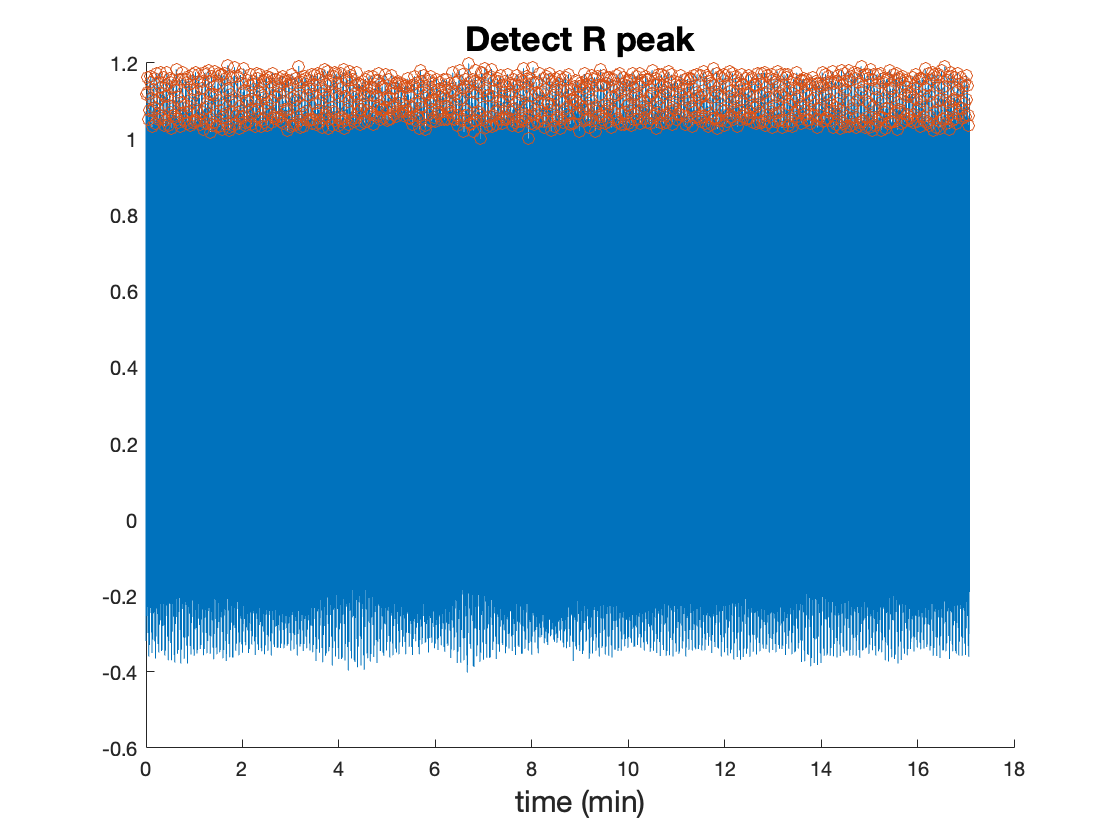

clc; clear; close all;
addpath('../src', '../data')
load('FakeECG')
% sample frequency is 200
time = linspace(0, numel(ecg)/200, numel(ecg));

% plot R peak
figure
hold on
plot(time/60, ecg);
plot(time(rpeaksidx)/60, ecg(rpeaksidx), 'o')

instan_freq = 200./diff(rpeaksidx');
R_peak_time = time(rpeaksidx(2:end)');
hold off
xlabel('time (min)', 'FontSize', 15)
title('Detect R peak', 'FontSize', 17)

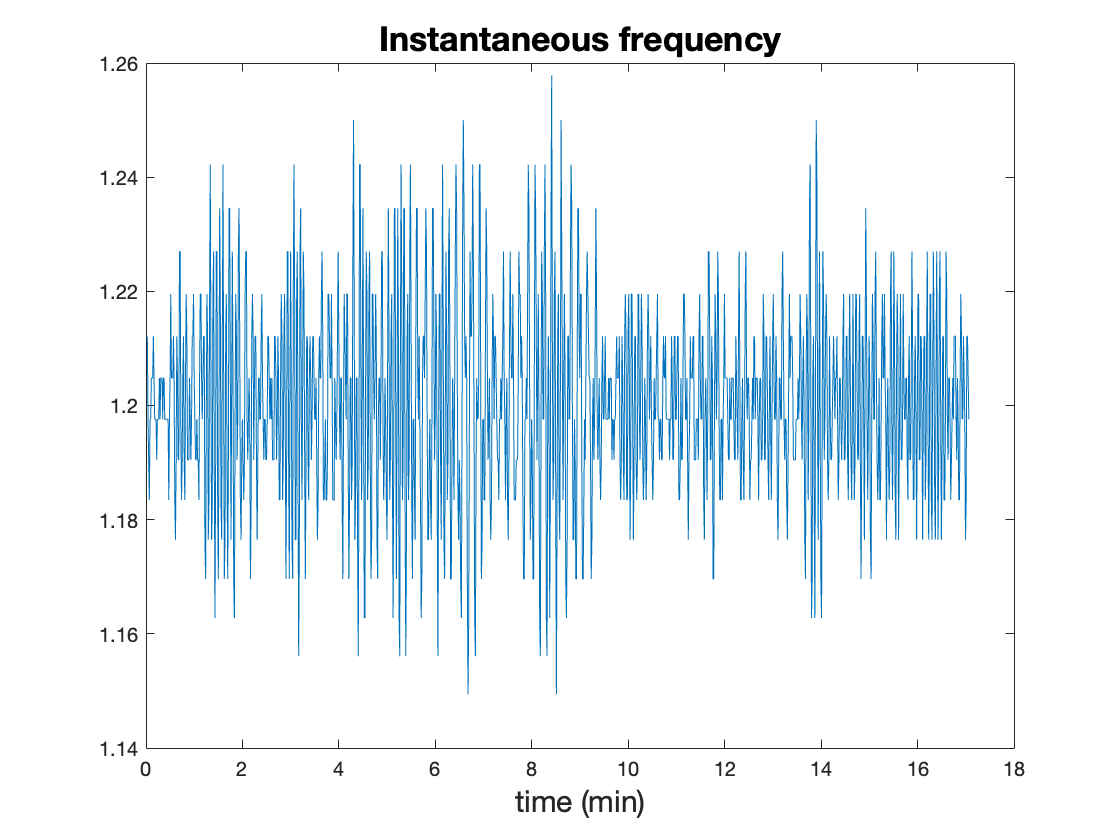


% plot instantaneous frequency (reciprocal of RR interval)
figure
plot(R_peak_time/60, instan_freq)
xlabel('time (min)', 'FontSize', 15)
title('Instantaneous frequency', 'FontSize', 17)

#### Apply DM via L-step lag map

L = 7; % L-step lag map
num_eigvec = 3;
bandwidth = 0.06;

% preprocessing by L-step lag map
X_lag = [];
for i = 1:numel(instan_freq)-(L-1)
    X_lag = [X_lag; instan_freq(i:i+L-1)];
end

% apply dm
[U, S] = DMapBasic(X_lag, 800, num_eigvec, bandwidth);

Step 1: Construct bandwidth of kernel function.
(info) No self-loop
(info) The bandwidth is given.
(info) There are no isolated point.
(info) The median number of points in bandwidth neighborhood is 800.
(info) The first 10% number of points in bandwidth neighborhood is 800.
Step 2: Construct affinity matrix
Step 3: Ignore the probability density function
Step 4: Solve the eigenvector


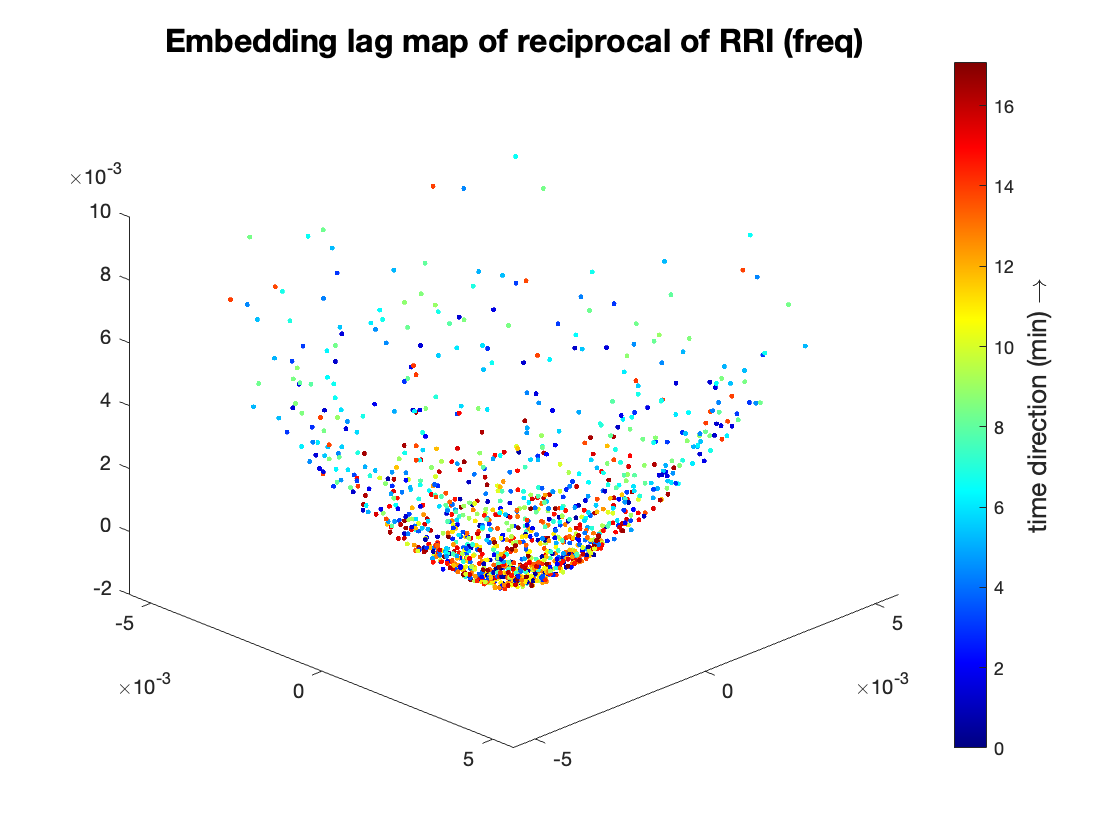


figure
numofpts = size(U, 1);
jetcustom = jet(numofpts);
colormap(jetcustom)

hold on
for i = 1:numofpts
    plot3(U(i, 1), U(i, 2), U(i, 3), '.', 'Color',  jetcustom(i, :))
end
view([45, 30])

colormap(jetcustom)
cb = colorbar;
caxis([0, R_peak_time(end)/60])
ylabel(cb,'time direction (min) \rightarrow', 'Fontsize', 13)
title('Embedding lag map of reciprocal of RRI (freq)', 'Fontsize', 16, 'FontWeight', 'bold')

## Wave shape

Please refer to [Lin, Malik and Wu (2019)](https://arxiv.org/abs/1907.00502).

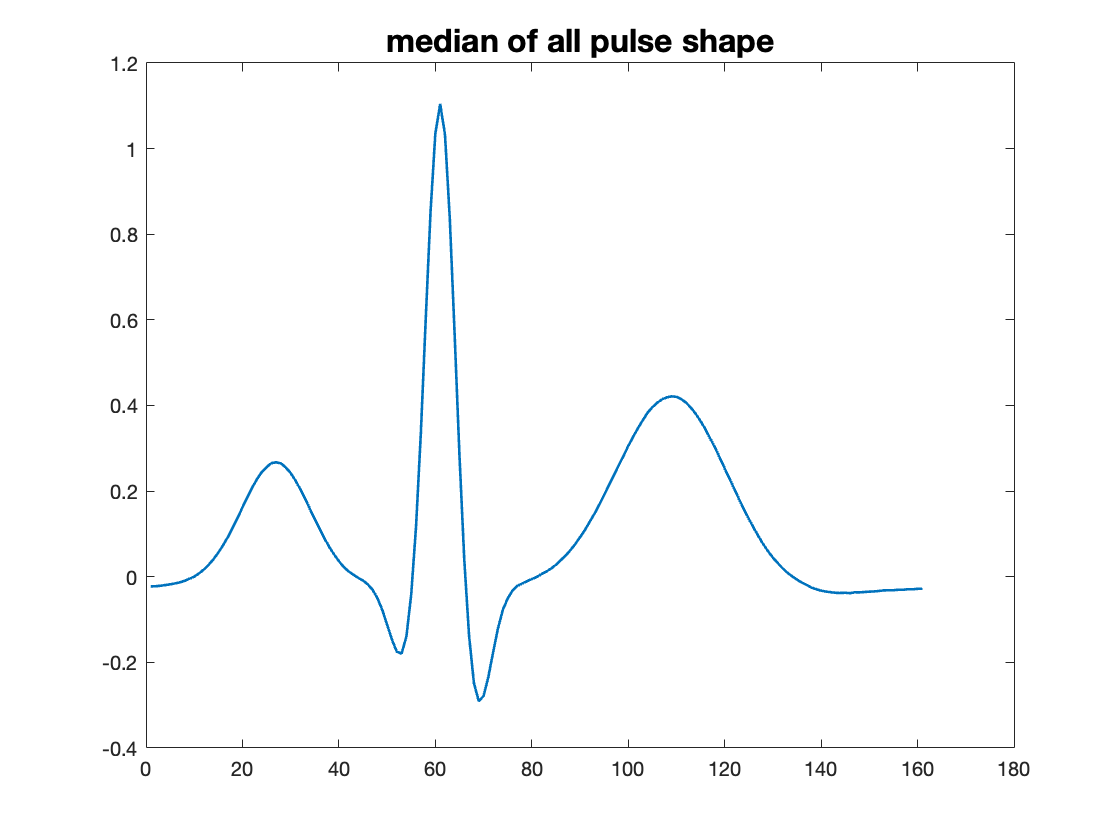

clc; clear; close all;
addpath('../src', '../data')
load('FakeECG')
% sample frequency is 200
time = linspace(0, numel(ecg)/200, numel(ecg));

% detect wave shape
front_sec = 0.3;
back_sec = 0.5;
numofRpeaks = numel(rpeaksidx);
X = [];
for i = 1:numofRpeaks
    ri = rpeaksidx(i);
    X = [X; ecg(ri-front_sec*200:ri+back_sec*200)'];
end

% plot median of all wave shape
figure
plot(median(X), 'LineWidth', 1.3)
title('median of all pulse shape', 'Fontsize', 16)

#### Apply DM via wave shape

% apply dm
num_eigvec = 3;
bandwidth = 1.3;
[U, S] = DMapBasic(X, 800, num_eigvec, bandwidth);

Step 1: Construct bandwidth of kernel function.
(info) No self-loop
(info) The bandwidth is given.
(info) There are no isolated point.
(info) The median number of points in bandwidth neighborhood is 800.
(info) The first 10% number of points in bandwidth neighborhood is 800.
Step 2: Construct affinity matrix
Step 3: Ignore the probability density function
Step 4: Solve the eigenvector


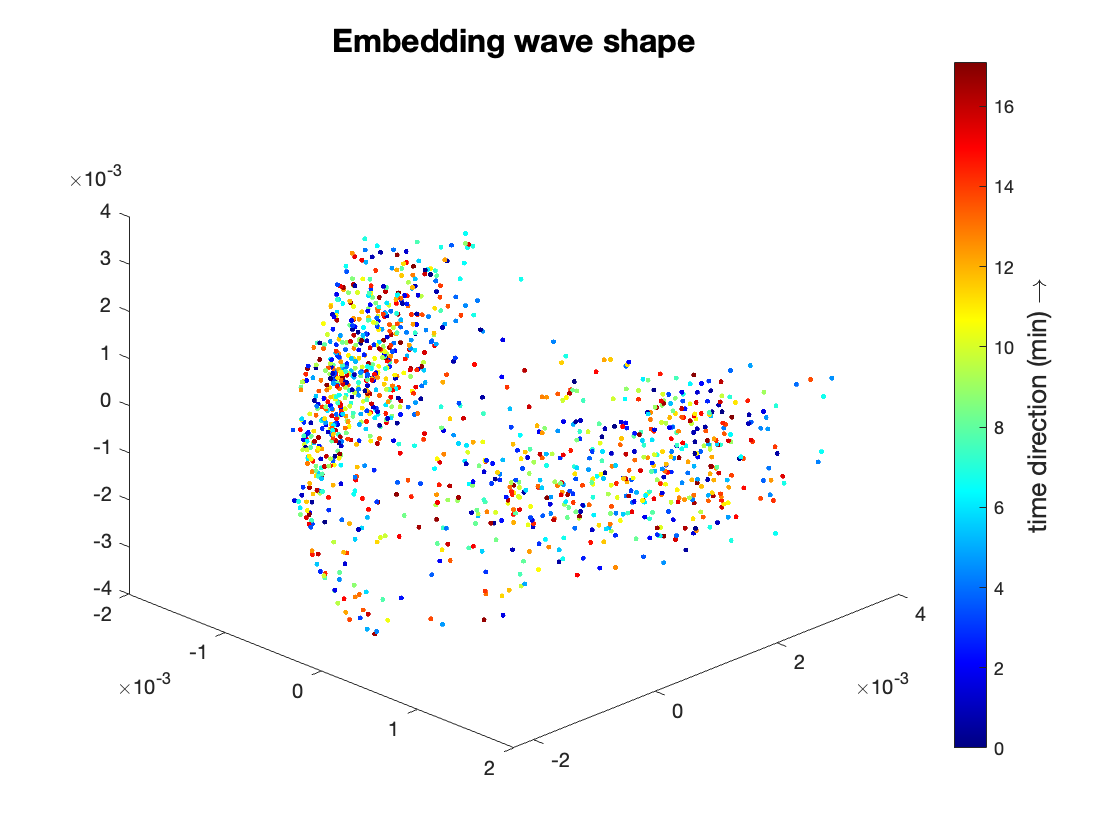


figure
numofpts = size(U, 1);
jetcustom = jet(numofpts);
colormap(jetcustom)

hold on
for i = 1:numofpts
    plot3(U(i, 1), U(i, 2), U(i, 3), '.', 'Color',  jetcustom(i, :))
end
view([45, 30])

colormap(jetcustom)
cb = colorbar;
caxis([0, time(end)/60])
ylabel(cb,'time direction (min) \rightarrow', 'Fontsize', 13)
title('Embedding wave shape', 'Fontsize', 16, 'FontWeight', 'bold')

## Spectrum

clc; clear; close all;
addpath('../src', '../data')
load('EEG_spectrum_subid.mat')
select_id = 5;
sub_ID = sub_ID(sub_ID == select_id);
X = X(sub_ID == select_id, :);
Y = Y(sub_ID == select_id, :);
time = (1:size(X, 1))*30/3600;

% apply dm
num_eigvec = 3;
bandwidth = 35;
[U, S] = DMapBasic(X, 800, num_eigvec, bandwidth);

Step 1: Construct bandwidth of kernel function.
(info) No self-loop
(info) The bandwidth is given.
(info) There are no isolated point.
(info) The median number of points in bandwidth neighborhood is 800.
(info) The first 10% number of points in bandwidth neighborhood is 800.
Step 2: Construct affinity matrix
Step 3: Ignore the probability density function
Step 4: Solve the eigenvector


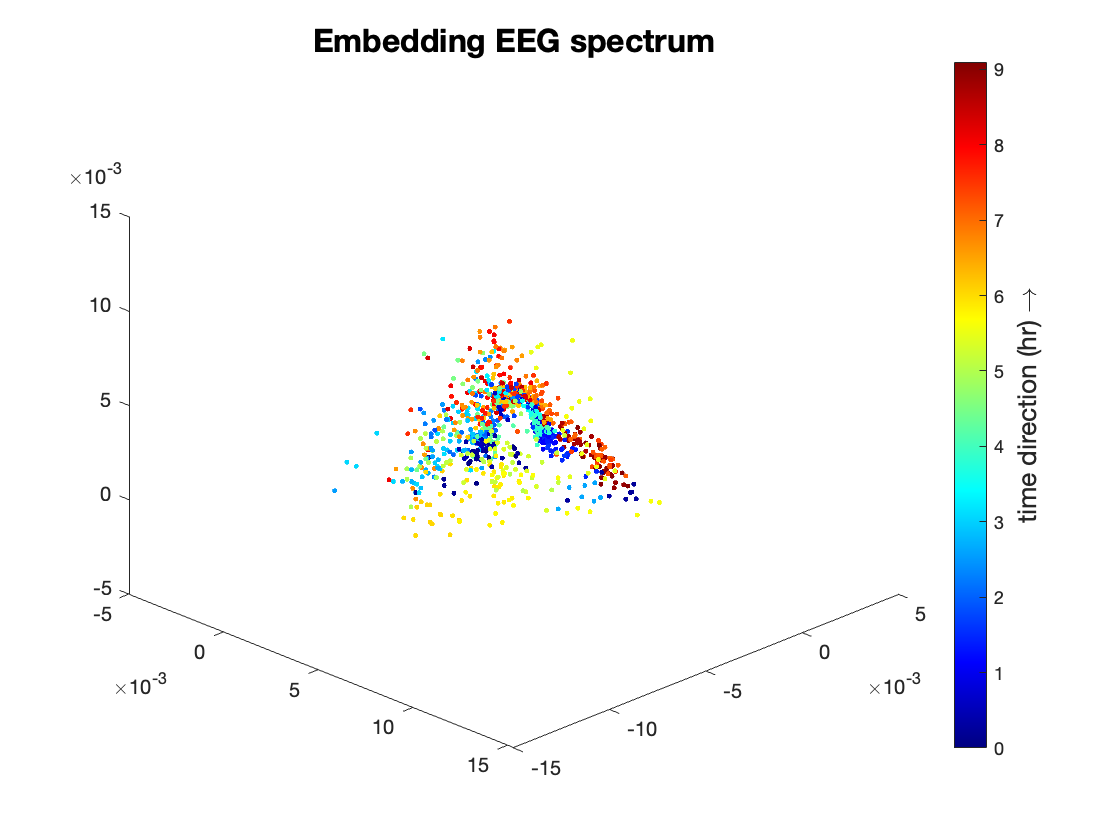


figure
numofpts = size(U, 1);
jetcustom = jet(numofpts);
colormap(jetcustom)

hold on
for i = 1:numofpts
    plot3(U(i, 1), U(i, 2), U(i, 3), '.', 'Color',  jetcustom(i, :))
end
view([45, 30])

colormap(jetcustom)
cb = colorbar;
caxis([0, time(end)])
ylabel(cb,'time direction (hr) \rightarrow', 'Fontsize', 13)
title('Embedding EEG spectrum', 'Fontsize', 16, 'FontWeight', 'bold')